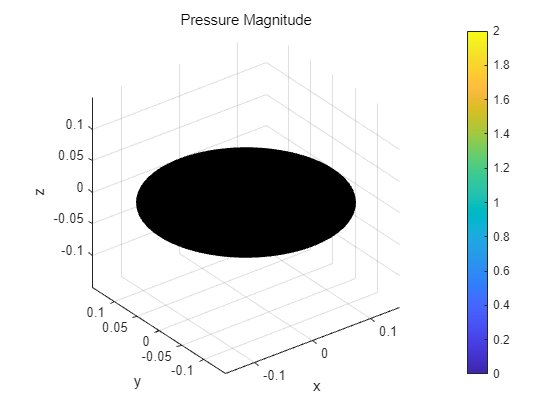

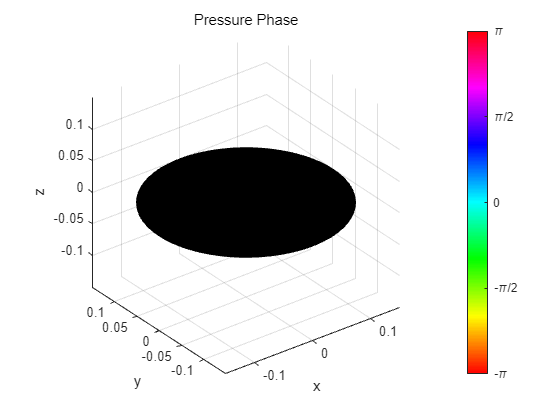

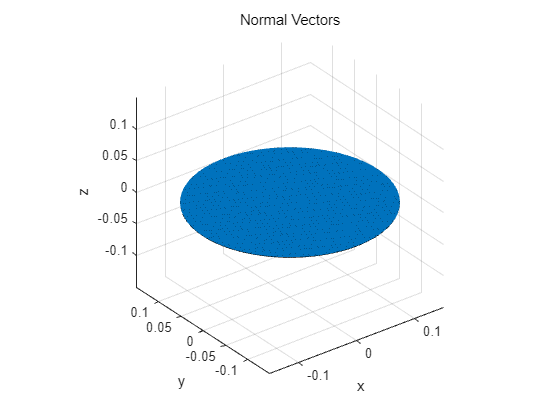

%% Transducer Design
transducer_info = [];

transducer_info.Frequency = 40000;
transducer_info.Pressure = 1;
transducer_info.Phase = 0;
transducer_info.Type = 'circle';
transducer_info.Radius = 0.15;
transducer_info.medium = 'air';

transducer_object = PFC_Make3DTransducer(transducer_info);

PFC_DrawTransducer3D(transducer_object, '-');


%% Frequency Domain
input_source = [];

input_source.Type = 'frequency';
input_source.reading_list = 40000; % [Hz]



%% Simulation Space
reading_pos_x = -150e-3 : 5e-3 : 150e-3;          % Simulation Area
reading_pos_y = -150e-3 : 5e-3 : 150e-3;          % Simulation Area
reading_pos_z = 0e-3 : 5e-3 : 2000e-3;          % Simulation Area



%% Run Frequency Domain Simulation

% xz plane
[Pressure_dxyz] = ...
PFC_CalculatePressureField(...
transducer_object, input_source,...                 % tx setting
reading_pos_x, 0, reading_pos_z);

Started at 2024-08-16 12:23:17
Finished at 2024-08-16 12:36:43
Progressed time : 00:13:25


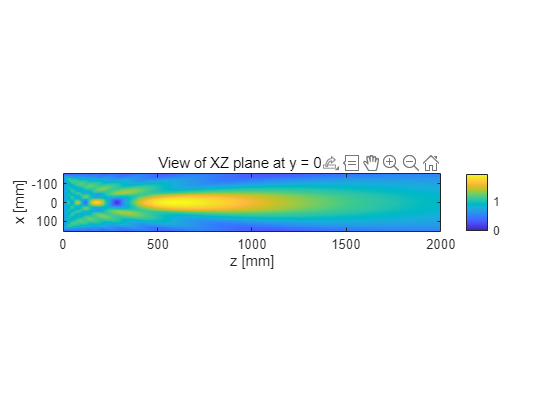


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
colorbar;
title('View of XZ plane at y = 0mm');
xlabel('z [mm]');
ylabel('x [mm]');

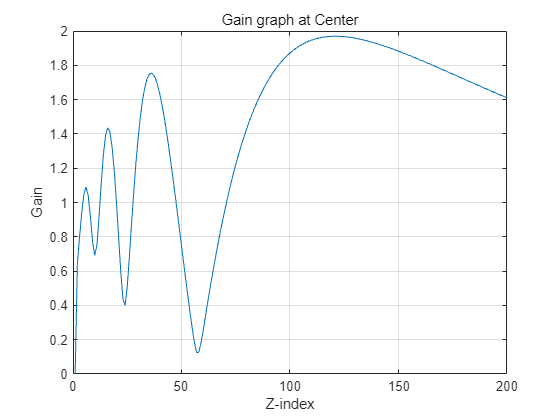

row_data = Pressure_dxyz_i(31, :);
plot(row_data);
xlabel('Z-index');
ylabel('Gain');
title('Gain graph at Center');
grid on;
xlim([0 200])


% xy plane
[Pressure_dxyz] = ...
PFC_CalculatePressureField(...
transducer_object, input_source,...                 % tx setting
reading_pos_x, reading_pos_y, 0.3);

Started at 2024-08-16 12:18:02
Finished at 2024-08-16 12:19:56
Progressed time : 00:01:53


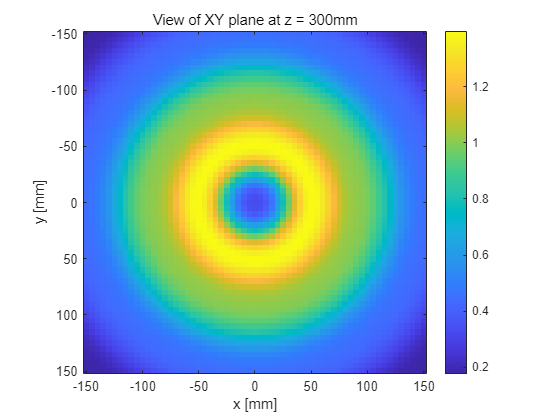


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
colorbar;
title('View of XY plane at z = 300mm');
xlabel('x [mm]');
ylabel('y [mm]');